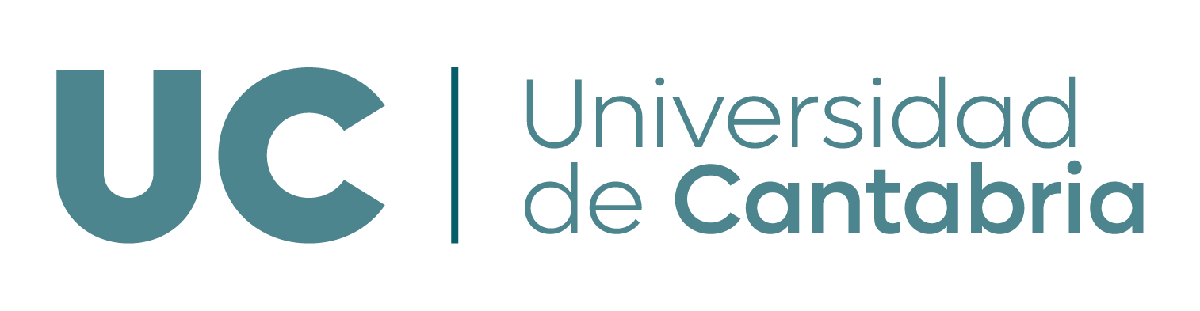

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# ** Aplicaciones lineales **

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Obtención de la matriz de una aplicación lineal en bases estándar

- Cálculo del núcleo y la imagen de una aplicación lineal

- Obtención de la matriz de una aplicación lineal en bases cualesquiera

Nota: Este guion no precisa del conocimiento de nuevas funciones de MATLAB, ya hemos trabajado con todas ellas anteriormente.

## **1. Matriz estándar de una aplicación **

Sea $f$ la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (2x, -3y+z) $$


Siempre podremos reescribirla en la forma $\vec{y}=A\vec{x}$ del siguiente modo:


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & -3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


Siendo $A$ su matriz asociada en bases canónicas (o matriz estándar).

A = [2 0 0; 0 -3 1]  % matriz estándar de la aplicación f

Fíjate que al ser una aplicación que va de $\mathbb{R}^3$ en $\mathbb{R}^2$, $A$ es de tamaño $2 \times 3$. Una vez tenemos $A$, es muy fácil calcular la imagen, de cualquier vector del espacio vectorial inicial, $\mathbb{R}^3$. Por ejemplo, la imagen del $\vec{v}=\left(\begin{array}{c}
     5\\  
     -7\\  
    - \pi\end{array}\right)$  será  $f(\vec{v})=\left(\begin{array}{ccc}
     2 & 0 & 0\\  
     0 & -3 & 1\end{array}\right)\left(\begin{array}{c}
     5\\  
     -7\\  
    - \pi\end{array}\right)=\left(\begin{array}{c}
     10\\  
     -21+ \pi\end{array}\right)$:

A*[5 -7 -pi]'  % imagen por f del vector (5, -7, -pi)

Fíjate además que las columnas de la matriz estándar $A$ corresponden con las imágenes de los vectores de la base canónica del espacio vectorial inicial,  $\mathbb{R}^3$ . Podemos comprobar esto facilmente:

A*[1 0 0]'  % primera columna de A (imagen del primer vector de la BC de R³)
A*[0 1 0]'  % segunda columna de A (imagen del segundo vector de la BC de R³)
A*[0 0 1]'  % tercera columna de A (imagen del tercer vector de la BC de R³)

## **2. Núcleo e imagen de una aplicación **

Veamos dos subespacios vectoriales muy importantes, el núcleo (subespacio del dominio o espacio inicial) y la imagen (subespacio del codominio o espacio final).

#### 2.1 Núcleo de una aplicación. 

Una vez tenemos la matriz de la aplicación, es muy fácil hallar su núcleo (o *kernel*). Recuerda que el núcleo de una aplicación lo forman los vectores del espacio inicial cuya imagen es el $\vec{0}$ del espacio final. Por tanto, partiendo de la matriz estándar $A$, hallar el núcleo de la apliación consiste en resolver el sistema homogéneo cuya matriz de coeficientes es precisamente $A$. Utilizando la función `null` obtendremos directamente una base de $Ker(f)$:

baseKer = null(A, 'r')  % base de Ker(f) --> dim(Ker(f))=1

Para resolver el sistema homogéneos con matriz de coeficientes A hemos utilizado la función `null, con la que` obtenemos directamente una base de $Ker(f)$. En este caso como la base del núcleo tiene un único vector de $\mathbb{R}^3$, el núcleo de $f$ es un subespacio de $\mathbb{R}^3$ con dimensión 1, una recta que pasa por el origen.

Para comprobar que la base que hemos obtenido es correcta, podemos comprobar que efectivamente la imagen del vector que la forma es el $\vec{0}$de $\mathbb{R}^2$:

A*baseKer  % al aplicarle A a la base de Ker(f), obtengo el vector 0 de R²

#### 2.2 Imagen de una aplicación. 

Por otro lado,  el espacio imagen de una aplicación $Im(f)$ es el subespacio generado por las columnas de $A$, formando estas un sistema generador. Para obtener una base deberemos quedarnos con un subconjunto linealmente independiente, una buena opción es escoger las columnas de A correspondientes a las columnas pivotales de su escalonada reducida.

rref(A)  % Im(f) tiene dimensión 2
% nos quedamos con las columnas 1 y 2 de A
base1Im = A(:, 1:2)  % esta sería una base de Im(f) --> dim(Im(f))=2 

Date cuenta de que se cumple la relación de dimensiones $dim(Ker(f))+dim(Im(f))=n$, donde $n$ es la dimensión del espacio vectorial inicial. En nuestro caso particular tendríamos $1+2=3$. Además, por definición, la dimensión de la imagen de la aplicación es igual el rango de A (número de columnas libres), es decir, $rg(A)=dim(Im(f))$

## **3. Matriz en bases cualesquiera de a una aplicación **

Por último veamos como obtener la matriz asociada a la aplacación $f$ en otras bases que no fueran las canónicas, por ejemplo $B_1 =\lbrace (1,0,1), (0,-1,-3), (-2,1,0)\rbrace$ en $\mathbb{R}^3$ y $B_2= \lbrace (1,1), (2,-1) \rbrace$ en $\mathbb{R}^2$. Para hallar dicha matriz, $M$, necesitaremos la matriz de paso de $B$ a la base canónica de $\mathbb{R}^3$ (llamémosla $P_{B_1}$)  y la matriz de paso de $B_2$ a la base canónica de $\mathbb{R}^2$ (llamémosla $P_{B_2}$). 

Sabemos que $P_{B_1 } =\left\lbrack \begin{array}{ccc}
1 & 0 & -2\\
0 & -1 & 1\\
1 & -3 & 0
\end{array}\right\rbrack$y $P_{B_2 } =\left\lbrack \begin{array}{cc}
1 & 2\\
1 & -1
\end{array}\right\rbrack$. 

A partir de aquí sería inmediato obtener $M$, pues sabemos que se cumple la relación $M={(P_{B_2})}^{-1}AP_{B_1}$.  

PB1 = [1 0 1; 0 -1 -3; -2 1 0]'  % matriz de paso de B a la BC de R³
PB2 = [1 1; 2 -1]'  %  matriz de paso de B' a la BC de R²
M = inv(PB2)*A*PB1  % matriz de f en la bases B y B'

¿Y si a partir de la matriz $M$ en bases cualesquiera queremos obtener la matriz estándar de la aplicación$A$? Simplemente despejando: 

$M={(P_{B_2})}^{-1}AP_{B_1} \leftrightarrow A=P_{B_2}A{(P_{B_1})}^{-1}$.  

## Ejercicios propuestos

**Ejercicio 1:**

Dada la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^3 \\
(x,y,z,t) \leadsto (x+2y+t , y+3z-t , 0) $$


- *a)* Obtén la forma implícita del núcleo y de la imagen de $f$

- *b)* Clasifica $f$

- *c)* Halla los vectores que tienen como imagen el vector $(2,2,0)$

- *d)* Halla los vectores que tienen como imagen el vector $(2,2,2)$

- *e)* Calcula una base de la imagen del subespacio $S$ de $\mathbb{R}^4$ engendrado por los vectores $\lbrace (0,0,3,2),(4,6,3,-1),(1,0,0,2) \rbrace$

**Ejercicio 2:**

Dada la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (3x-2y, x-z) $$


- *a)* ¿Cuál es la dimensión de la imagen?

- *b)* Obtén una base del núcleo de $f$

- *c)* Obtén una base de la imagen de $f$

- *d)* Clasifica $f$

- *e)* Obtén una base de la imagen del subespacio $S \in \mathbb{R}^3$ cuya ecuación implícita es $x+y+z=0$

- *f)* Obtén la matriz de $f$ en las bases $B=\lbrace (1,0,-1), (0,2,3), (0,-1,0)\rbrace$ de $\mathbb{R}^3$ y $B' = \lbrace (1,0), (-1,2)\rbrace$ de $\mathbb{R}^2$

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.

- Guiones para Matlab realizado por Ana Casanueva para la asignatura de Álgebra y Geometría de los grados de Recursos Energéticos y Recursos Mineros.